# Median Filter Experiments (Part 1C)

## Before running

- `median_filter.m` must be in the same folder as this file.

- `cameraman.tif` and `circuit.tif` are images already from MATLAB.

## Contents

- **Section 1. Compare with medfilt2:** runs `median_filter` and `medfilt2` on the same image with noise and prints the max difference inside the border.

- **Section 2. Comparing different noise levels:** applies a 3x3 median to an image at 2%, 10%, 20%, 30% and 50% noise.

- **Section 3. Comparing window sizes:** applies 3x3, 6x6, 1x10, 9x9 and 10x1 windows to an image with 5% noise.

- **Section 4. Other sample image:** applies 3x3 and 9x9 windows to an image at 5% noise.

## 1. Compare with medfilt2

Runs `median_filter` and `medfilt2` on the same image with noise and prints the max difference inside the border.

% medfilt2 is only used as a checker here, not used in the actual function

% cameraman at half size with 2% salt and pepper noise, same as median_test.m
img = imread('cameraman.tif');
img = imresize(img, 0.5);
noisy_img = imnoise(img, 'salt & pepper', 0.02);

% window sizes to compare
win_sizes = [3 3; 6 6; 1 10];

[h, w] = size(noisy_img);

for i = 1:size(win_sizes, 1)
    M = win_sizes(i, 1);
    N = win_sizes(i, 2);

    % feed same image through both filters
    my_result = median_filter(noisy_img, M, N);
    medfilt2_result = medfilt2(im2double(noisy_img), [M N]);

    % skip the border pixels since my implementation differs from built in
    skip_r = ceil((M - 1) / 2);
    skip_c = ceil((N - 1) / 2);
    rows_in = (1 + skip_r):(h - skip_r);
    cols_in = (1 + skip_c):(w - skip_c);

    % max difference left inside the image, 0 = match
    diff_in = abs(my_result(rows_in, cols_in) - medfilt2_result(rows_in, cols_in));
    max_diff = max(max(diff_in));
    fprintf('window %d x %d: max diff = %g\n', M, N, max_diff);
end

window 3 x 3: max diff = 0
window 6 x 6: max diff = 0
window 1 x 10: max diff = 0


## 2. Comparing different noise levels

Applies a 3x3 median filter to `cameraman.tif` with a salt and pepper noise of 2%, 10%, 20%, 30% and 50%.

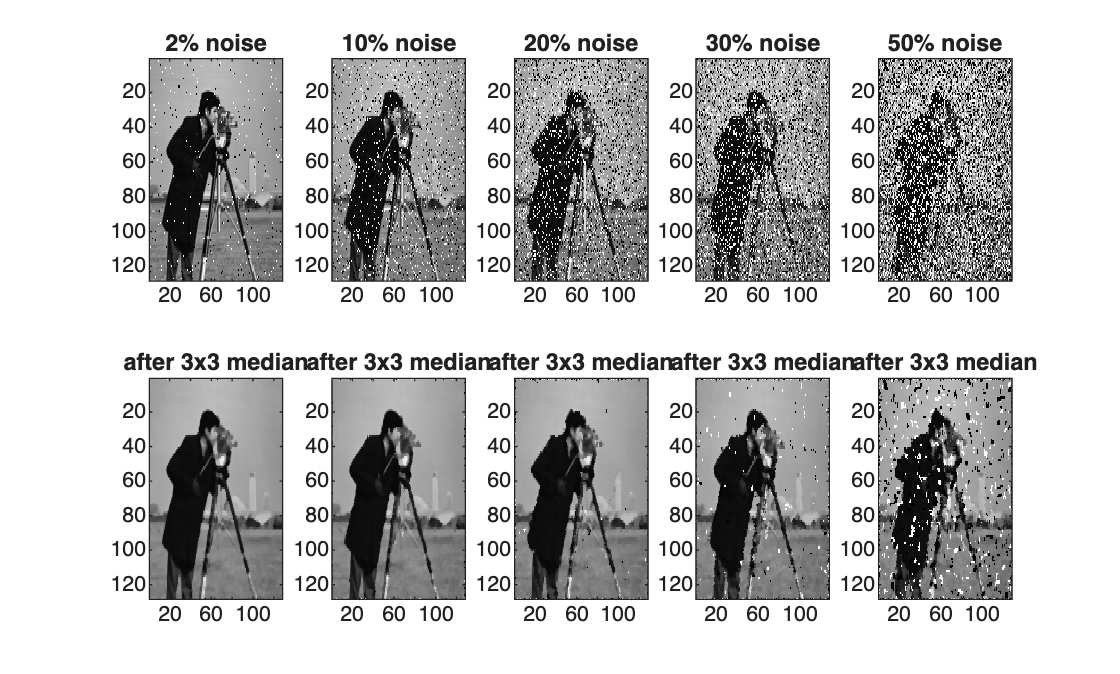

% fixed random seed so the same noise is generated on every run
rng(1);

% image at half size
clean_img = imread('cameraman.tif');
clean_img = imresize(clean_img, 0.5);

noise_levels = [0.02 0.1 0.2 0.3 0.5];

figure
colormap(gray);

for i = 1:length(noise_levels)
    % add noise to the clean image
    noisy_img = imnoise(clean_img, 'salt & pepper', noise_levels(i));
    % filter it with a 3x3 window
    cleaned_img = median_filter(noisy_img, 3, 3);
    
    % top row: noisy image, 0 to 1 range so all panels have the same brightness scale
    subplot(2, 5, i);
    imagesc(im2double(noisy_img), [0 1]);
    title([num2str(noise_levels(i) * 100) '% noise']);
    % bottom row: filtered image
    subplot(2, 5, i + 5);
    imagesc(cleaned_img, [0 1]);
    title('after 3x3 median');
end

% save results
saveas(gcf, 'noise_levels.png');

## 3. Comparing window sizes

Applies five window sizes (3x3, 6x6, 1x10, 9x9, 10x1) to `cameraman.tif` with 5% noise. 

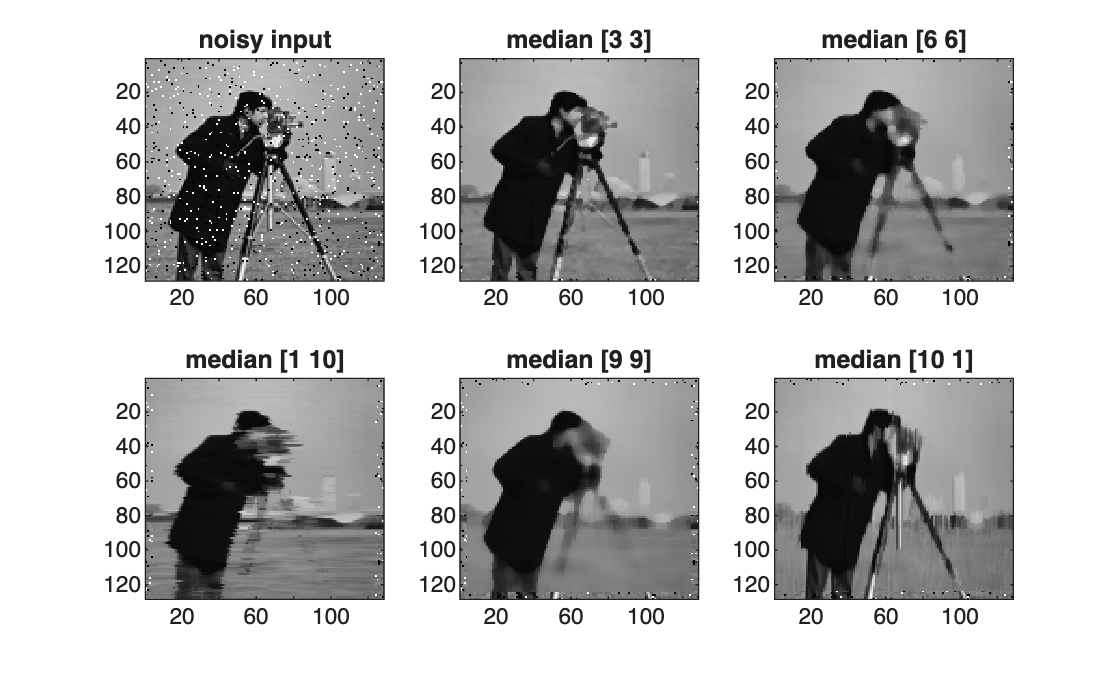

% given window sizes (3x3, 6x6, 1x10) plus 9x9 and 10x1

% fixed random seed so the same noise is generated on every run
rng(1);

% image at half size
clean_img = imread('cameraman.tif');
clean_img = imresize(clean_img, 0.5);

% same 5% noise for every window size
noisy_img = imnoise(clean_img, 'salt & pepper', 0.05);

% window sizes
win_sizes = [3 3; 6 6; 1 10; 9 9; 10 1];

figure
colormap(gray);

% noisy picture before any filtering
subplot(2, 3, 1);
imagesc(im2double(noisy_img), [0 1]);
title('noisy input');

for i = 1:size(win_sizes, 1)
    M = win_sizes(i, 1);
    N = win_sizes(i, 2);
    result = median_filter(noisy_img, M, N);

    subplot(2, 3, i + 1);
    imagesc(result, [0 1]);
    title(['median [' num2str(M) ' ' num2str(N) ']']);
end
% save results
saveas(gcf, 'window_sizes.png');

## 4. Other sample image

Tests the filter on `circuit.tif`, a MATLAB sample image (not given in the files). It was chosen because it has thin lines and sharp corners, the fine detail a median window can wipe out, which the cameraman image barely has. The 3x3 and 9x9 windows are applied at 5% noise.

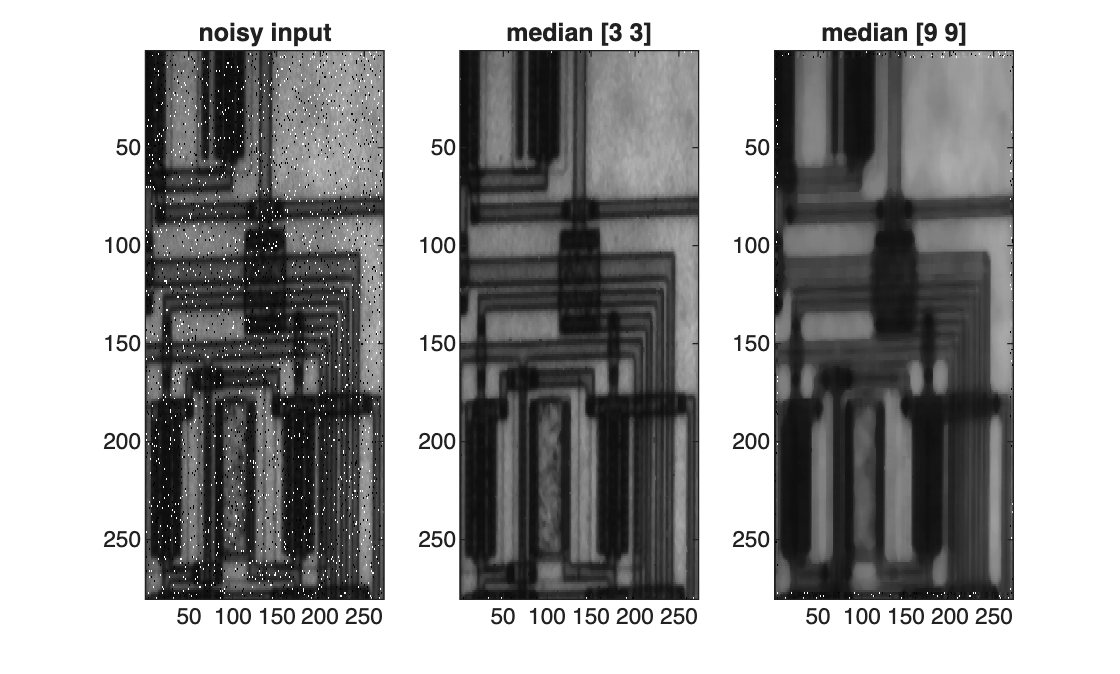

% fixed random seed so the same noise is generated on every run
rng(1);

% circuit.tif is already from matlab
img = imread('circuit.tif');

% 5% salt and pepper noise
noisy_img = imnoise(img, 'salt & pepper', 0.05);

% window sizes
win_sizes = [3 3; 9 9];

figure
colormap(gray);

% noisy picture before any filtering
subplot(1, 3, 1);
imagesc(im2double(noisy_img), [0 1]);
title('noisy input');

for i = 1:size(win_sizes, 1)
    M = win_sizes(i, 1);
    N = win_sizes(i, 2);
    result = median_filter(noisy_img, M, N);

    subplot(1, 3, i + 1);
    imagesc(result, [0 1]);
    title(['median [' num2str(M) ' ' num2str(N) ']']);
end

% save results
saveas(gcf, 'circuit_results.png');